# Exam August 2018

## Problem 1: Compute PSD from data using Pisarenko (sinusoid with additive white noise)

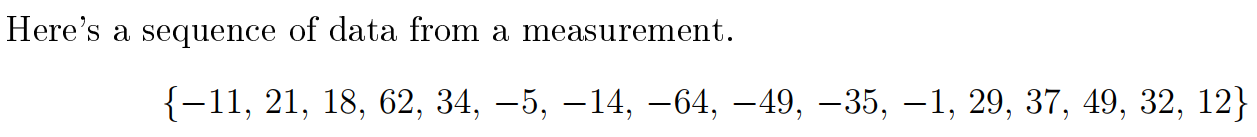

### [✔] 1) Compute and plot the autocorrelation for lags 0 to 4

x = [-11, 21, 18, 62, 34, -5, -14, -64, -49, -35, -1, 29, 37, 49, 32, 12];

% Estimate autocorrelation using data
[r_xx, ell] = xcorr(x, 'biased');

% Print out the lags 0 to 4
mid = floor(numel(ell)/2)+1;
r_xx(mid:mid+4)

ans = 	1.0e+03 *

    1.2256    0.8664    0.3979   -0.2310   -0.7027


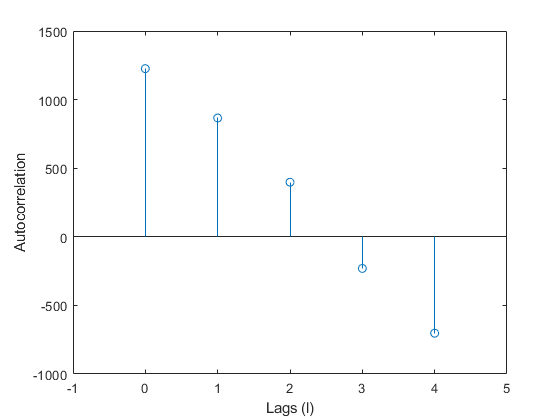

% Plot the results
stem(0:4, r_xx(mid:mid+4))
xlim([-1, 5])
xlabel('Lags (l)')
ylabel('r_xx(l)')

### [✔] 2) Compute the power spectral density assuming a Pisarenko model.

*Assume that the signal is a sinusoid in additive white Gaussian noise.*

The Pisarenko method can be used to recover the sinusoidal frequencies of a corrupted signal $x\left(n\right)$ given two assumptions:

- The signal $x\left(n\right)$ consists of $p$ sinusoids that has been corrupted by white noise.

- The autocorrelation matrix of size $\left(p+1\right)\times \left(p+1\right)$ is known or can be estimated from data

The Pisarenko method consists of the following steps:

***Step 1***: Compute the autocorrelation matrix ${\mathbf{R}}_{\mathrm{xx}}$

***Step 2:*** Find the eigenvector corresponding to the smallest minimum eigenvalue. The elements of this eigenvector is the parameters of the $\mathrm{ARMA}\left(2p,2p\right)$ model 

***Step 3:*** Find the frequencies $\left\lbrace \;f_i \;\right\rbrace$ of the sinusoids. This can be done by computing the roots of the polynomial $A\left(z\right)$ in Eq. (14.5.4) in the book. This polynomial has $2p$ poles on the unit circle which correspond to the frequencies of the system.

        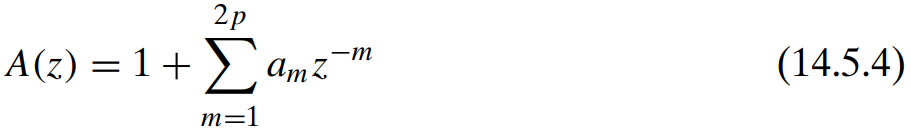

***Step 4*****:** Solve Eq. (14.5.11) for the signal powers $\left\lbrace P_i \right\rbrace$

        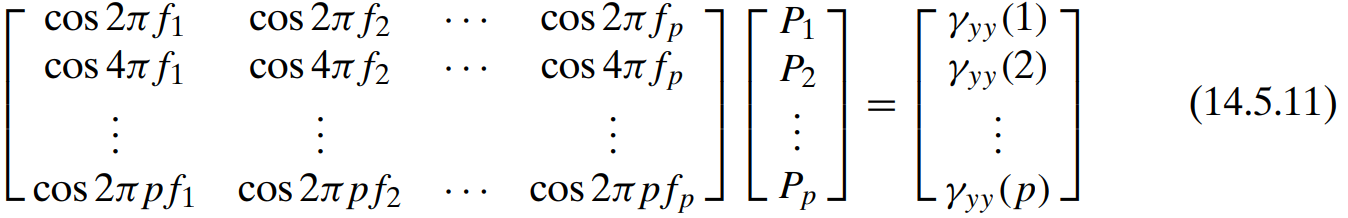

where 

- $\gamma_{\mathrm{yy}} \left(1\right),\gamma_{\mathrm{yy}} \left(2\right),\cdots ,\gamma_{\mathrm{yy}} \left(p\right)$ are the estimated autocorrelation values 

- $P_i =\frac{A_i^2 }{2}$ is the average power of the $i$th sinusoid and $A_i$ is the corresponding amplitude

***Step 5***: Estimate the amplitude $A_i =\sqrt{2P_i }$

These steps are coded up in the `pisarenko()` function (see at end of this document):

[F, A, P, lambda_min] = pisarenko(r_xx(mid:mid+4), 1)

F = 0.0938

A = 45.6585

P = 1.0423e+03

lambda_min = 183.2154

We can describe the signal as:

        
$$x\left(n\right)=45\ldotp 6585\;\mathrm{cos}\left(2\pi \cdot 0\ldotp 0938\right)+w\left(n\right)$$


where $w\left(n\right)$ is white noise with variance $\sigma_w^2 =183\ldotp 2154$

To compute the power spectral density, we need to find the autocorrelation function of the sinusoid.

In ADSI Problem 4.4, we found that the autocorrelation of a real sinusoid given by $y\left(n\right)=A\;\mathrm{cos}\left(\omega n+\phi \right)$ where $A$ and $\omega$ are real constants and $\phi$ is a random variable with $\phi ~U\left(0,2\pi \right)$ is:

        
$$r_{\textrm{yy}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


The autocorrelation function of white noise with variance $\sigma_w^2$ is given by:

        
$$r_{\mathrm{ww}} \left(\ell \right)=\sigma_w^2 \delta \left(\ell \right)$$


Combining these results, the general autocorrelation function of our signal is:

        
$$r_{\mathrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)+\sigma_w^2 \delta \left(\ell \right)$$


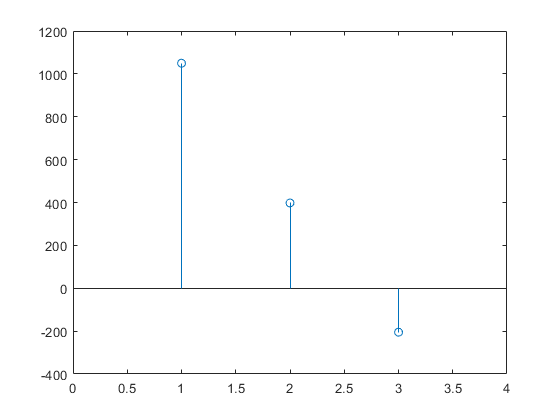

% Plot the autocorrelation function of the sinusoid
ell = 1:3;
r_ww = lambda_min * (ell == 1);
r_xx_p = (A^2/2) * cos(2*pi*F*ell) + r_ww;
stem(r_xx_p)
xlim([0, 4])

The power spectral density is the Fourier transform the autocorrelation function which is given by:

        
$$S\left(\omega \right)=\frac{A^2 }{2}\pi \left\lbrack \delta \left(\omega -\omega_0 \right)+\delta \left(\omega +\omega_0 \right)\right\rbrack +\sigma_w^2$$


A, F, lambda_min

A = 45.6585

F = 0.0938

lambda_min = 183.2154

Using the values found via the Pisarenko, the PSD is:

        
$$S\left(\omega \right)=\frac{{\left(45\ldotp 6585\right)}^2 }{2}\pi \left\lbrack \delta \left(\omega -2\pi \cdot 0\ldotp 0938\right)+\delta \left(\omega +2\pi \cdot 0\ldotp 0938\right)\right\rbrack +183\ldotp 2154$$


### [✔] 3. Discuss whether the Pisarenko model can be considered appropriate for the given data.  

Plotting the limited amount of samples, we see a sinusiodal shape. Since Pisarenko model assumes sinuisoidal signal that has been corrupted by white noise then it can be appropriate model.

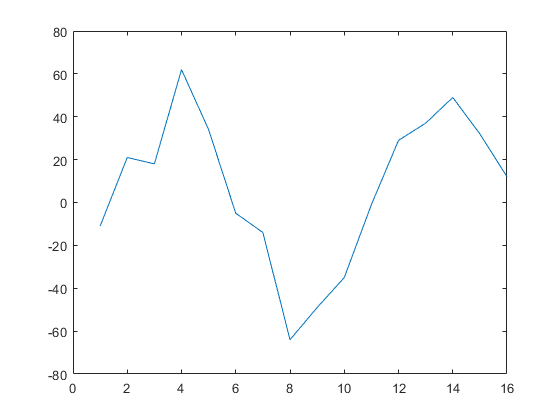

plot(x)

## Problem 2: True/False Questions

*For the statements given below, state whether they are true or false and justify your answer for each statement.  *

### [✔] 1) Is a filter invertible if the poles of the system function lies within the unit circle?

A filter $H\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)}$ is said to be stable and causal if all the poles of $H\left(z\right)$ are inside the unit circle.

If the inverse filter $H_{\mathrm{inv}} \left(z\right)=\frac{A\left(z\right)}{B\left(z\right)}$ has to be stable and causal, then all the poles of $H_{\textrm{inv}} \left(z\right)$ must be inside the unit circle or equivalently all zeros of $H\left(z\right)$ must be inside the unit circle.

So if we want the inverse filter to be stable, then the answer is **false**. Typically, we want an inversable filter to be minimum-phase which means that the filter *and* its inverse must causal and stable.

### [✔] 2) If a signal is scaled by 2, does its autocorrelation also scale by 2?

The autocorrelation of a signal $x\left(n\right)$ is defined as:

        
$$r_x \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


We can compute the autocorrelation of signal $y\left(n\right)=2x\left(n\right)$ as follows:

        
$$r_y \left(\ell \right)=E\left\lbrack y\left(n\right)y\left(n-\ell \right)\right\rbrack$$


        
$$r_y \left(\ell \right)=E\left\lbrack 2\;x\left(n\right)2x\left(n-\ell \right)\right\rbrack$$


        
$$r_y \left(\ell \right)=4\cdot E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_y \left(\ell \right)=4r_x \left(\ell \right)$$


So the answer is **false**!

### [?] 3) Under stationary conditions, a least mean square (LMS) adaptive filter with proper choice of the step-size will converge to the Wiener-Hopf solution.

## Problem 3: Matched Filters

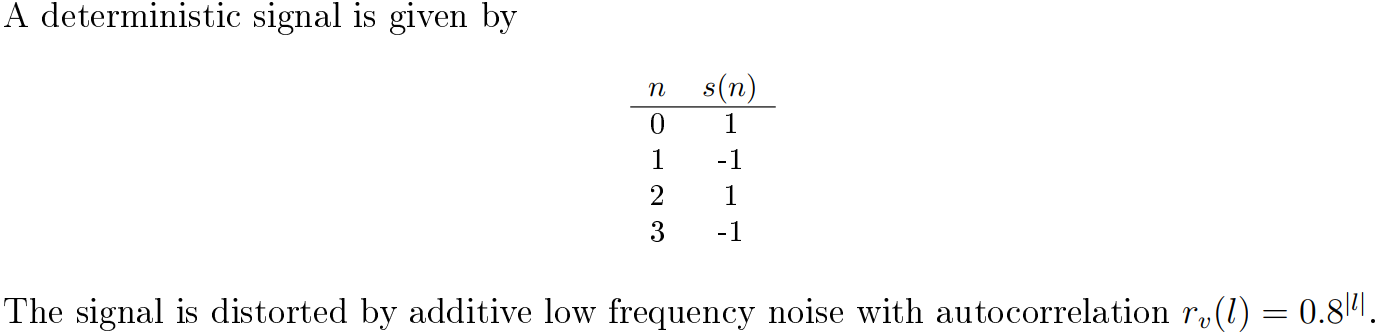

clear variables;

### [✔] 1) Design a matched filter to improve the signal to noise ratio and comment on the improvement.  

The impulse response of the matched filter is given by:

        

where $R_v$ is autocorrelation matrix of noise and $\kappa$ is the normalisation factor. 

Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        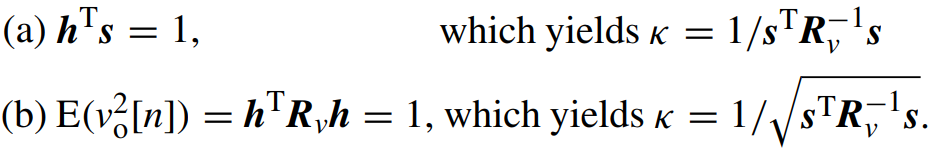

s = [1, -1, 1, -1]';

p = numel(s); % Signal length

% The autocorrelation matrix must be p x p since
% its inverse is multiplied by a p-tap signal s(n)
ell = 0:p-1;
r_vv = 0.8.^ell;
R_vv = toeplitz(r_vv);

% Compute normalisation factor (b)
k = 1/sqrt(s'*(R_vv\s)); % Same as 1/sqrt(s'*inv(R_vv)*s)

% Compute the filter
h = k*(R_vv\s); % Same as k*inv(R_vv)*s

% Print the matched filter coefficients
h

h =     0.9449
   -1.7008
    1.7008
   -0.9449


The optimum SNR is given by:

        

Assuming the attenuation factor $a=1$:

a = 1;
SNR = a^2 * s' * (R_vv\s)

SNR = 28.0000

### [✔] 2) Can the signal to noise ratio be improved by using more than two blocks?  

Yes, the SNR can be improved. With three blocks, the SNR is increased to 46:

s = [1, -1, 1, -1, 1, -1]';
p = numel(s);
ell = 0:p-1;
r_vv = 0.8.^ell;
R_vv = toeplitz(r_vv);
k = 1/sqrt(s'*(R_vv\s));
h = k*(R_vv\s);

a = 1;
SNR = a^2 * s' * (R_vv\s)

SNR = 46.0000

## Problem 4: Wiener Filtering

### 1) Determine the autocorrelation function, $r_s \left(l\right)$

We can **identify** an **LTI** system by inputing white noise to it and measuring the corresponding output.


$$r_s \left(\ell \right)=E\left\lbrack s\left(n\right)s\left(n-\ell \right)\right\rbrack$$


### 2) Solve the Wiener-Hopf Equation

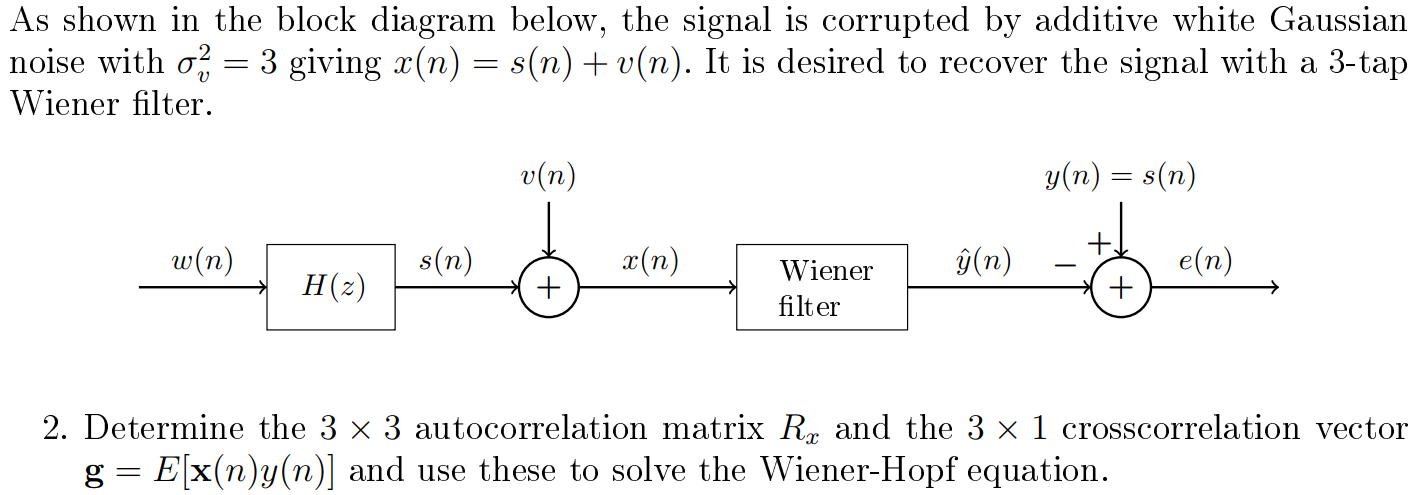

### 3) Discuss whether 3 taps is an optimum choice for this problem?

## Problem 5: Probability Density Function

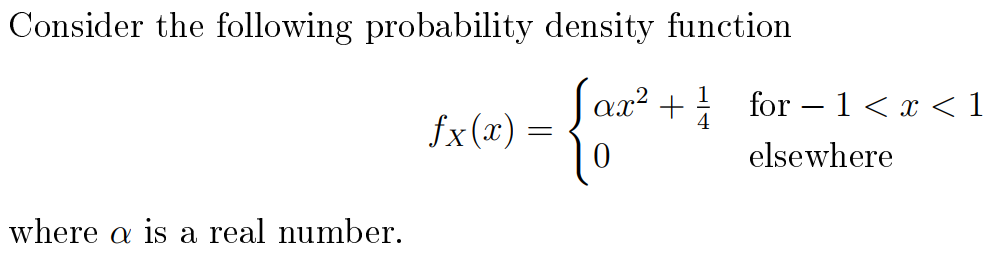

### [✔] 1) Find a valid probability density function

A valid probability density function is given by:

        
$$\int_{-\infty }^{\infty } f_X \left(x\right)\;\mathrm{dx}=1$$


We need to compute:

        
$$\int_{-1}^1 \alpha x^2 +\frac{1}{4}\textrm{dx}$$


For convenience and to avoid silly mistakes, use MATLAB:

syms x a
int(a*x^2 + 1/4, x, -1, 1)

$$ans = \frac{2\,a}{3}+\frac{1}{2}$$

Solve the equation for $a$ in MATLAB:

solve(int(a*x^2 + 1/4, x, -1, 1) - 1)

$$ans = \frac{3}{4}$$

Let us check the results:

int(3/4 * x^2 + 1/4, x, -1, 1)

$$ans = 1$$

For $f_X \left(x\right)$ to be a valid probability density function, $a$ must be:

        
$$a=\frac{3}{4}$$


### [✔] 2) Compute the probability given a probability density function?

p = int(3/4 * x^2 + 1/4, x, 1/4, 3/4)

$$p = \frac{29}{128}$$

vpa(p)

$$ans = 0.2265625$$

The answer is:

        
$$\mathrm{Pr}\left(\frac{1}{4}<X\le \frac{3}{4}\right)=\frac{29}{128}=0\ldotp 2265625$$


### [✔] 3) Compute the expected value a function:

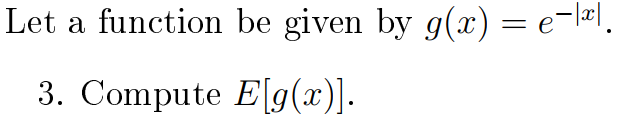

We need to compute:

        
$$E\left\lbrack g\left(x\right)\right\rbrack =\int_{-\infty \;}^{\infty } g\left(x\right)f_X \left(x\right)\;\mathrm{dx}=\int_{-1\;}^1 e^{-|x|} \cdot \frac{3}{4}x^2 +\frac{1}{4}\;\mathrm{dx}$$


syms x
f = exp(-abs(x)) * 3/4 * x^2 + 1/4

$$f = \frac{3\,x^{2}\,{\mathrm{e}}^{-\left|x\right|}}{4}+\frac{1}{4}$$

int(f , x, -1, 1 )

$$ans = \frac{7}{2}-\frac{15\,{\mathrm{e}}^{-1}}{2}$$

vpa(int(f , x, -1, 1 ))

$$ans = 0.74090419121418258803357172378904$$

The answer is:

        
$$E\left\lbrack g\left(x\right)\right\rbrack \approx 0\ldotp 74$$


## Functions

function [F, A, P, lambda_min]=pisarenko(r_xx, p)
    % Estimates the frequencies and amplitudes using the Pisarenko method
    %  r_xx: autocorrelation sequence starting from zero. 
    %        The length of ACRS must be at least 2p+1.
    %  p: assumed number of sinusoids in the signal
    %  F: normalised frequencies of the sinuoids
    %  A: amplitudes of the sinuoids
    if numel(r_xx) < 2*p+1
        error(strcat('The length of ACRS must be at least ', int2str(2*p+1)));
    end
    
    % Compute the autocorrelation matrix
    R_xx = toeplitz(r_xx(1:2*p+1));
    
    % Perform the eigendecomposition
    [eigvecs, eigvals] = eigs(R_xx, size(R_xx, 1), 'smallestreal');
    
    eigvals = diag(eigvals);
    lambda_min = eigvals(1);
    
    % Find the eigenvector 'a' corresponding to the smallest eigenvalue.
    % The function eigs() sorts eigenvectors, so just pick the first column.
    a = eigvecs(:, 1);
    
    % Ensure that a_0 = 1 (this is by definition)
    a = a / a(1);
    
    % The elements of this eigenvector corresponds to the parameters
    % of an ARMA(2p, 2p) model: a_0, a_1, ..., a_2p where p: number of sinusoids
    % The polynomial A(z) in (14.5.4) has 2p poles on the unit circle.
    % Obtain the poles by finding the roots of the system.
    z = roots(a);
    
    % Estimate frequencies
    F = zeros(p, 1);
    for i = 1:p
        % The poles come in pairs. Each pair is complex conjugate
        % of one another. Only use one of them and find the absolute value.
        z_i = z(2*i);
        F(i) = abs(angle(z_i)) / (2*pi);
    end
    
    % Build the matrix of cosines
    C = zeros(p);
    for i = 1:p
        for j = 1:p
            C(i, j) = cos(i * 2*pi * F(j));
        end
    end
    
    % Start the ACRS from the second element according to equation (14.5.11)
    gamma = r_xx(2:p+1);
    
    % Solve equation (14.5.11) for P
    P = C\gamma; % Same as `inv(C)*gamma` but faster and more accurate
    
    % Since P=A^2/2, we can compute the amplitude A=sqrt(2*P)
    A = sqrt(2 * P);
end